# Practice NODC Cast work

% Load Data
cd('C:\Users\ajs82292\Desktop\Research\Matlab\Source')
load("02cleanNODC.mat")

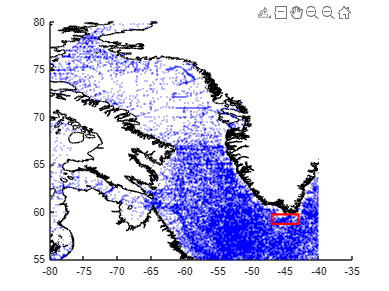

% Map
clf
hold on
plot(cx,cy,'k')
xlim([-80,-35])
ylim([55,80])
scatter(lon,lat,1,'MarkerFaceColor','b','MarkerEdgeAlpha','0') ;
rectangle('Position',[-47,58.7,4,1],'EdgeColor','red','LineWidth',2)
hold off

%Limit NODC Data to Square only to make interpolation easier
Squarelonindicies = (lon >= -47) & (lon <=-43) ;
lon = lon(Squarelonindicies) ;
lat = lat(Squarelonindicies) ;
sal = sal(Squarelonindicies) ;
temp = temp(Squarelonindicies) ;
mon = mon(Squarelonindicies);
day = day(Squarelonindicies);
yea = yea(Squarelonindicies);
watdep = watdep(Squarelonindicies);
dep = dep(Squarelonindicies) ;
% Lat
Squarelatindicies = (lat >= 58.7) & (lat <=59.7) ;
lon = lon(Squarelatindicies) ;
lat = lat(Squarelatindicies) ;
sal = sal(Squarelatindicies) ;
temp = temp(Squarelatindicies) ;
mon = mon(Squarelatindicies) ;
day = day(Squarelatindicies);
yea = yea(Squarelatindicies);
watdep = watdep(Squarelatindicies) ;
dep = dep(Squarelatindicies) ;

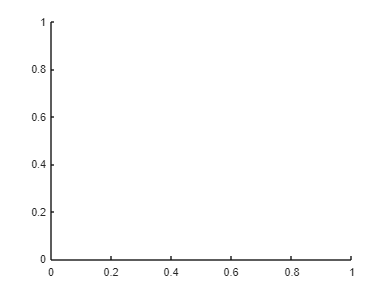

%Map New Restricted Data
clf
hold on
plot(cx,cy,'k')
xlim([-80,-35])
ylim([55,80])
scatter(lon,lat,2,'MarkerFaceColor','b','MarkerEdgeAlpha','0') ;
rectangle('Position',[-47,58.7,4,1],'EdgeColor','red','LineWidth',2)
hold off

%Interpolate every 1 m 
max_length = max(cellfun(@numel,dep)) ;
DepInterval = (0:1:max_length)';
int_temp = {} ;
for i = 1:1:length(dep)
    int_temp{1,i} = interp1(dep{1,i},temp{1,i}, DepInterval, 'linear') ;
end
%Salinity 
int_sal = {} ;
for i = 1:1:length(dep)
    int_sal{1,i} = interp1(dep{1,i},sal{1,i}, DepInterval, 'linear') ;
end

% Set Up Month Matrices
Julyindex = (mon == 7);
Augindex = (mon == 8);
Septindex = (mon == 9);
Octindex = (mon == 10);
JulyT = int_temp(Julyindex) ;
AugT = int_temp(Augindex) ;
SeptT = int_temp(Septindex) ;
OctT = int_temp(Octindex) ;
JulyS = int_sal(Julyindex) ;
AugS = int_sal(Augindex) ;
SeptS = int_sal(Septindex) ;
OctS = int_sal(Octindex) ;
% Matrices for Calculations
JulyT = cell2mat(JulyT);
AugT = cell2mat(AugT);
SeptT = cell2mat(SeptT);
OctT = cell2mat(OctT);
JulyS = cell2mat(JulyS);
AugS = cell2mat(AugS);
SeptS = cell2mat(SeptS);
OctS = cell2mat(OctS);

% Computations
%Averages
JulyTM = mean(JulyT, 2, 'omitnan') ;
AugTM = mean(AugT, 2, 'omitnan') ;
SeptTM = mean(SeptT, 2, 'omitnan') ;
OctTM = mean(OctT, 2, 'omitnan') ;
JulySM = mean(JulyS, 2, 'omitnan') ;
AugSM = mean(AugS, 2, 'omitnan') ;
SeptSM = mean(SeptS, 2, 'omitnan') ;
OctSM = mean(OctS, 2, 'omitnan') ;
% Standard Deviations
JulyTStd = std(JulyT, 0, 2, 'omitnan') ;
AugTStd = std(AugT, 0, 2, 'omitnan') ;
SeptTStd = std(SeptT, 0, 2, 'omitnan') ;
OctTStd = std(OctT, 0, 2, 'omitnan') ;
JulySStd = std(JulyS, 0, 2, 'omitnan');
AugSStd = std(AugS, 0, 2, 'omitnan');
SeptSStd = std(SeptS, 0, 2, 'omitnan');
OctSStd = std(OctS, 0, 2, 'omitnan');

% Subtract Each Cast by monthly Average for Anomaly
JulyTA = JulyT - JulyTM ;
JulySA = JulyS - JulySM ;
AugTA = AugT - AugTM ;
AugSA = AugS - AugSM ;
SeptTA = SeptT - SeptTM ;
SeptSA = SeptS - SeptSM ;
OctTA = OctT - OctTM ;
OctSA = OctS - OctSM ;

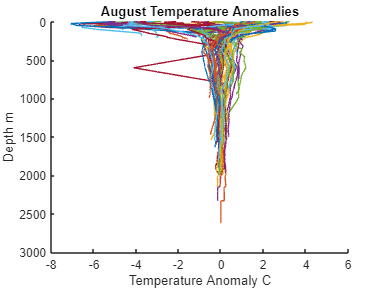

%August TA
clf
hold on
plot(AugTA,DepInterval)
title('August Temperature Anomalies')
xlabel('Temperature Anomaly C')
ylabel('Depth m')
axis ij
hold off

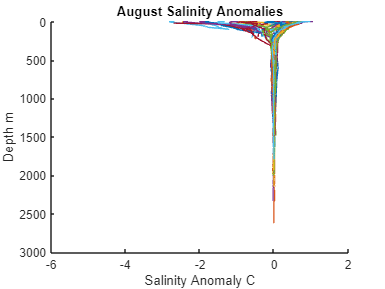

%August Salinity Anmoaly
clf
hold on
plot(AugSA,DepInterval)
title('August Salinity Anomalies')
xlabel('Salinity Anomaly C')
ylabel('Depth m')
axis ij
hold off

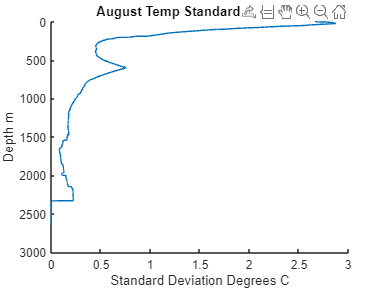

% August Temperature Std
clf
hold on
plot(AugTStd,DepInterval)
title('August Temp Standard Deviation')
xlabel('Standard Deviation Degrees C')
ylabel('Depth m')
axis ij
hold off

% August Salinity Std
clf
hold on

plot(AugSStd,DepInterval)

Unrecognized function or variable 'AugSStd'.

title('August Sal Standard Deviation')
xlabel('Standard Deviation Sal')
ylabel('Depth m')
axis ij
hold off

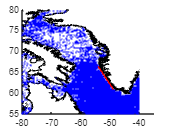

% Work on simplified coastline (ginput) (Needs to have better coast
% selection)
clf
hold on
plot(cx,cy,'k')
xlim([-80,-35])
ylim([55,80])
% Already selected coastline points
run = 2 ;
for i = 1:1:1
    if run == i 
        SWgcoast = ginput(2);
        save ("SWgcoast.mat", "SWgcoast");
    end
end
load('SWgcoast.mat')
scatter(lon,lat,1,'MarkerFaceColor','b','MarkerEdgeAlpha','0') ;
plot (SWgcoast(:,1),SWgcoast(:,2) ,'r')
hold off

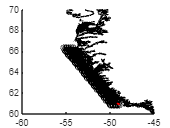

% Creation of Rectangles on Coast (length is wrong, length of the side needs to be 20 not the interval)
clf
m = ((SWgcoast(2,2)-SWgcoast(1,2))/(SWgcoast(2,1)-SWgcoast(1,1))) ; %slope of simplified coastline
b = SWgcoast(1,2)-m*SWgcoast(1,1) ; % y intercept of coastline
m_perpindicular = -1/m ;
width = 10 ; % km
length = 20 ; % km
y_SWcoast = SWgcoast(2,2) - SWgcoast(1,2) ; % difference between y points
x_SWcoast = SWgcoast(2,1)- SWgcoast(1,1) ; % difference between x points
anglerectangles = atan2d(y_SWcoast,x_SWcoast) ; % degrees
angle_recd = deg2rad(anglerectangles) ;
SWlength = distance(SWgcoast(1,2),SWgcoast(1,1),SWgcoast(2,2),SWgcoast(2,1)) ; % degrees upscaling will be a pain
SWlengthkm = deg2km(SWlength) ; % km
lengthdeg = km2deg(length) ;
num_rectangles = floor(SWlengthkm / width);
% Calculate y_intervals in order for length of line to = 20 km (still not
% correct)
startLat = deg2rad(SWgcoast(2,2));
startLon = deg2rad(SWgcoast(2,1));
R = 6371 ; % km
bearing = anglerectangles - 90 ; % find angle in relation to y-axis
bearing = deg2rad(bearing);
endLat = asin(sin(startLat) * cos(length / R) + cos(startLat) * sin(length / R) * cos(bearing));
endLat = rad2deg(endLat);
startLat = rad2deg(startLat) ;
y_deg_interval = endLat - startLat ;
y_intervals = SWgcoast(2,2):-y_deg_interval:SWgcoast(1,2) ;
widthdeg = 111.320*cosd(y_intervals) ;
widthdeg = width./widthdeg ;
zero_x = (y_intervals-b) / m ;
ten_x = zero_x - widthdeg ;
twenty_x = ten_x - widthdeg ;
thirty_x = twenty_x - widthdeg ;
fourty_x = thirty_x -widthdeg ;
fifty_x = fourty_x -widthdeg ;  
%Plot
exampleline_x1 = ([fifty_x(1,1),zero_x(1,1)]) ;
exampleline_x2 = ([fifty_x(1,2),zero_x(1,2)]) ;
exampleline_y1 = ([y_intervals(1,1),y_intervals(1,1)]) ;
exampleline_y2 = ([y_intervals(1,2),y_intervals(1,2)]) ;
hold on 
plot(zero_x,y_intervals, 'k')
plot(ten_x,y_intervals, 'k')
plot(twenty_x,y_intervals, 'k')
plot(thirty_x,y_intervals, 'k')
plot(fourty_x,y_intervals, 'k')
plot(fifty_x,y_intervals,'k') 
scatter(zero_x,y_intervals, 'k')
scatter(ten_x,y_intervals, 'k')
scatter(twenty_x,y_intervals, 'k')
scatter(thirty_x,y_intervals, 'k')
scatter(fourty_x,y_intervals, 'k')
scatter(fifty_x,y_intervals,'k') 
plot(exampleline_x1,exampleline_y1, 'k')
plot(exampleline_x2,exampleline_y2, 'k')
plot(cx,cy, 'k')
xlim([-60,-45])
ylim([60,70])
plot(vertices(:,1),vertices(:,2), 'r')
hold off

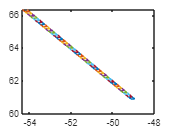

% Finding Casts within parallelogram 
num_intervals = numel(ten_x) - 1; % number of parallelograms
for i = 1:1:num_intervals
    % Define the vertices of the parallelogram
    vertices = [ten_x(i), y_intervals(i); ten_x(i+1), y_intervals(i+1); zero_x(i+1), y_intervals(i+1); zero_x(i), y_intervals(i)];
    vertices_cell{i} = vertices;  % Store vertices in the cell array
end
hold on
for i = 1:numel(vertices_cell)
plot(vertices_cell{i}(:,1),vertices_cell{i}(:,2))
end
hold off

magnitude = sind(anglerectangles)*widthdeg

magnitude = 0.0651

ydeg = sqrt(magnitude^2-widthdeg^2)

ydeg = 0.0000 + 0.0621i

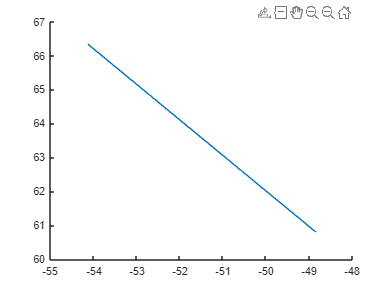

clf
hold on 
plot(SWgcoast(:,1),SWgcoast(:,2))

% Find nearest cx,cy and distance (need to fix shouldn't be linear)
coastlinepoints = [cx,cy] ;
lonlat = [lon',lat'] ;
idx_nearest = knnsearch(coastlinepoints, lonlat);
closest_cx = cx(idx_nearest);
closest_cy = cy(idx_nearest);
distances = sqrt((lon'-closest_cx).^2 +(lat'-closest_cy).^2) ; % ' to translate lat lon
d_lat = lat' - closest_cy ; 
d_lon = lon' - closest_cx ;
angles = atan2d(d_lat,d_lon) ;
angles = mod(angles, 360);
rads = deg2rad(angles) ;

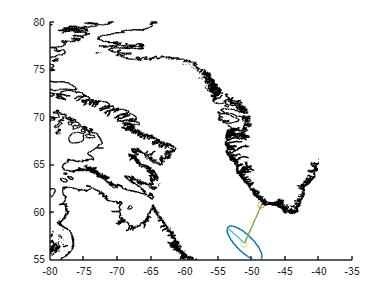

% Creation of angled ovals
clf
hold on
testx = [closest_cx(1,1),lon(1,1)] ;
testy = [closest_cy(1,1),lat(1,1)] ;
testx2 = [-53.5712,lon(1,1)] ;
testy2 = [58.2901,lat(1,1)] ;
tilt_angle = pi/2 ;
a = 3 ;
b = 1 ;
theta = linspace(0, 2*pi, 100) ; % Angles from 0-2pi
center = [lon(1,1), lat(1,1)] ;
x = center(1) + a * cos(theta) ;
y = center(2) + b * sin(theta) ;
x = x - lon(1,1) ;
y = y - lat(1,1) ;
R = [cos(rads(1,1)+tilt_angle), -sin(rads(1,1)+tilt_angle); sin(rads(1,1)+tilt_angle), cos(rads(1,1)+tilt_angle)];
rotated_coords = R * [x ; y] ;
x = rotated_coords(1, :) ;
y = rotated_coords(2, :) ;
x = x + lon(1,1) ;
y = y + lat(1,1) ;
plot(x,y)
scatter(closest_cx(1,1),closest_cy(1,1))
scatter(lon(1,1),lat(1,1))
plot(cx,cy, 'k')
xlim([-80,-35])
ylim([55,80])
plot(testx,testy)
plot(testx2,testy2)
hold off

% Major axis of ellipse
a_km = 7.5 ; % distance of major axis (this will change with distance from coastline)
lat1 = deg2rad(lat) ;
lon1 = deg2rad(lon) ;
bearing = rads ; % in radians
bearing = bearing' ;
R = 6371 ; % r of earth
d = a_km/R ; % Distance to Radians
lat2 = asin(sin(lat1) .* cos(d) + cos(lat1) .* sin(d) .* cos(bearing)) ;
lon2 = lon1 + atan2(real(sin(bearing) .* sin(d) .* cos(lat1)), real(cos(d) - sin(lat1) .* sin(lat2)));
lat2 = rad2deg(lat2) ;
lon2 = rad2deg(lon2) ;
latdiff = abs(lat2-lat) ; % degrees - degrees
londiff = abs(lon2-lon) ;
Amagnitudedistance = sqrt(latdiff.^2+londiff.^2) ;
%Minor Axis of Elipse (scaled to a)
asource = Amagnitudedistance ;
distances = sqrt((lon'-closest_cx).^2 +(lat'-closest_cy).^2) ;
equalization = 2.5 ; % distance at which a = b and becomes a circle
scaleb = min(1,distances/equalization) ;
scaleb = scaleb' ;
bsource =  min(asource,asource.*scaleb) ;

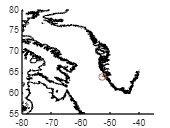

% Test, ensure B is never larger than a or the angle won't match
clf
hold on
indiv = 44 ;
tilt_angle = pi/2 ;
a = asource(1,indiv) ; % (Constant)
b = bsource(1,indiv) ; % b defined above
theta = linspace(0, 2*pi, 100) ; % Angles from 0-2pi
center = [lon(1,indiv), lat(1,indiv)] ;
x = center(1) + a * cos(theta) ;
y = center(2) + b * sin(theta) ;
x = x - lon(1,indiv) ;
y = y - lat(1,indiv) ;
R = [cos(rads(indiv,1)+tilt_angle), -sin(rads(indiv,1)+tilt_angle); sin(rads(indiv,1)+tilt_angle), cos(rads(indiv,1)+tilt_angle)];
rotated_coords = R * [x ; y] ;
x = rotated_coords(1, :) ;
y = rotated_coords(2, :) ;
x = x + lon(1,indiv) ;
y = y + lat(1,indiv) ;
plot(x,y)
plot(cx,cy,'k')
xlim([-80,-35])
ylim([55,80])
scatter(closest_cx(indiv,1),closest_cy(indiv,1))
scatter(lon(1,indiv),lat(1,indiv))
testx = [closest_cx(indiv,1),lon(1,indiv)] ;
testy = [closest_cy(indiv,1),lat(1,indiv)] ;
plot(testx,testy)
hold off 